# **Input offset nulling**

**Auteurs:**

**Datum: 07-10-2025**

**Project: Meetversterker**

**Revisie: 1**

## **Changelog**

## **Inleiding**

Voor het meetversterker project moet er een versterker gerealiseerd worden. Het ingang signaal van de sterker kan varieren van de 0.5mV t/m 5mV. Voor de versterker wordt er een Instrumental Amplifier (INA) gerealiseerd. Hiervoor is de eis dat de LM358 wordt gebruikt. De LM358 heeft een input offset ($\left.V_{\mathrm{os}} \right)$ tolerantie van max: $\pm 7\mathrm{mV}$. Vergeleken met het ingangsignaal, is de input offset een zware factor.

Daarom moet er een input offset nulling schakeling gerealiseerd worden die dit effect kan verzwaken tot bijna null.

Voor het meetversterkerproject moet een versterker gerealiseerd worden met een ingangssignaal van $0,5\mathrm{mV}$ tot $5\mathrm{mV}$. De versterker wordt opgebouwd als een **instrumentatieversterker (INA)** op basis van de **LM358** op-amp. 

De LM358 heeft een typische **input offset voltage (**$V_{\mathrm{os}}$**)** van $\pm 2\mathrm{mV}$ (maximaal $\pm 7\mathrm{mV}$). Aangezien dit vergelijkbaar is met het ingangssignaal, is correctie noodzakelijk. Daarom wordt een **input offset nulling-schakeling** toegepast om de offsetspanning te compenseren tot vrijwel nul.

Bij een versterking van 1000x, zou een offset van 2 mV aan de ingang resulteren in een uitgangsoffset van **2 V**. Dit kan de meetnauwkeurigheid aanzienlijk beïnvloeden.

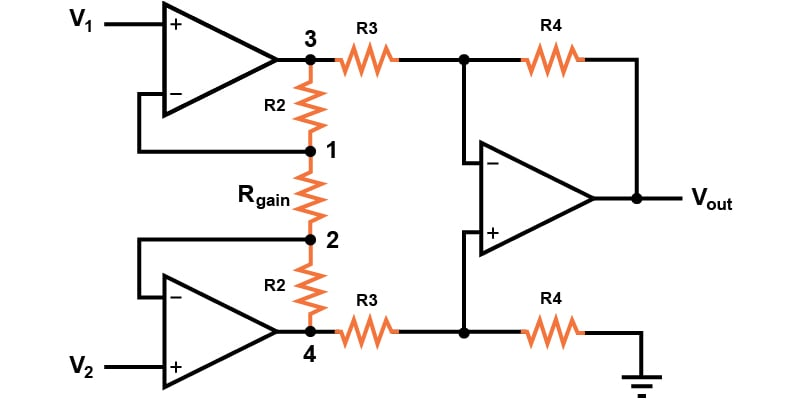

## **Oplossing**

Er bestaan verschillende methodes om de input offset te compenseren, waaronder:

- **Stroominjectie: **Hierbij wordt een kleine corrigerende stroom in één van de ingangen geïnjecteerd om de offset te balanceren.

- **Spanningsreferentie (lifting): **Hierbij wordt de referentiespanning van de niet-inverterende ingang aangepast om de effectieve offsetspanning op nul te brengen.

In de praktijk wordt dit vaak gerealiseerd met een **trimpotentiometer (trim pot)** die tussen de voedingsrails (bijv. $\pm 15V$) is aangesloten (Analog Devices, 2001).

Door het middencontact van de trimpot op de op-amp-ingang aan te sluiten, kan de **offset handmatig worden ingesteld** zodat de uitgangsspanning effectief 0V is bij nul ingangssignaal.

Het resulterende netwerk kan worden voorgesteld als een **Thevenin-equivalent circuit**, waarbij de effectieve offsetcompensatiespanning bepaald wordt door de stand van de trimpot.

In de praktijk wordt de afregeling uitgevoerd door de ingang kort te sluiten (0 V) en de trimpot te verdraaien totdat de uitgang exact 0 V is. Een nadeel van deze methode is dat de offset door temperatuur- of verouderingseffecten kan verschuiven. Voor hogere stabiliteit kunnen digitale potentiometers of **auto-zero op-amps** worden toegepast. Maar aangezien dat niet in het scope van het project valt, is dit geen relevante oplossing.

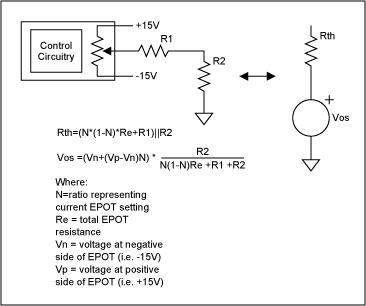

Thevenin equivelante circuit for trimpot circuit.

De offset nulling circuits kunnen ook in verschillende versterker configuraties voorkomen. Hierbij wordt er bij de INA gekomposeerd op de differentiaal versterker kant. Hierbij komt de trimpot circuit aan de niet-inventerende kant. Hierbij wordt de referentie spanning "opgelift", waardoor de $V_{\mathrm{cm}}$ ook gaat varieren. Als gevolg gaat de op-amp's uitgang ook varieren om $V_- =V_+$ te krijgen, aangezien het spannings potentiaal 0V moet zijn bij de ingangen.

De **offset-nulling schakeling** kan in verschillende versterkerconfiguraties worden toegepast. Bij een **instrumentatieversterker (INA)** wordt de compensatie meestal uitgevoerd aan de **differentiaalversterker**. In dit geval wordt de **trimpot** aangesloten op de niet-inverterende ingang, waarbij het middencontact van de trimpot verbonden is met de referentiespanning.

Door de stand van de trimpot te wijzigen, wordt de **referentiespanning licht “opgelift” of verlaagd**, waardoor de $V_{\mathrm{os}}$ effectief wordt gecompenseerd. De uitgangsspanning van de op-amp past zich automatisch aan om het potentiaalverschil tussen de ingangen op $0V$ te houden.

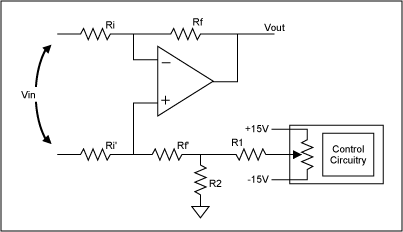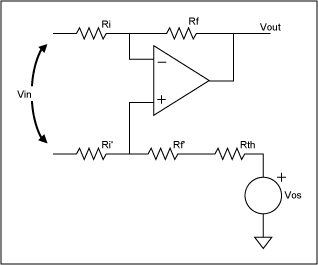

## Formules

clear
syms Vp Vn N Re R1 R2

Formules voor thevenins weerstand en voltage


$$V_{\textrm{th}} =\left(V_n +\left(V_p -V_n \right)\cdot N\right)\cdot \frac{R_2 }{N\left(1-N\right)\cdot R_e +R_1 +R_2 }$$



$$R_{\textrm{th}} =\left(N\cdot \left(1-N\right)\cdot R_e +R_1 \right)\;\|\;R_2$$


Vos = (Vn + (Vp - Vn) * N) * (R2 / (N * (1-N) * Re + R1 + R2))

$$Vos = \frac{R_{2}\,\left(\mathrm{Vn}-N\,\left(\mathrm{Vn}-\mathrm{Vp}\right)\right)}{R_{1}+R_{2}-N\,\Re\,\left(N-1\right)}$$


Rt = (N * (1-N) * Re + R1);
Rth = (Rt * R2) / (Rt + R2)

$$Rth = \frac{R_{2}\,\left(R_{1}-N\,\Re\,\left(N-1\right)\right)}{R_{1}+R_{2}-N\,\Re\,\left(N-1\right)}$$

Substitute the resistors

Resistors = {1000, 10, 20e3};
Rth = subs(Rth, {R1, R2, Re}, Resistors);
Vos = subs(Vos, {R1, R2, Re}, Resistors);

Substitute the voltages

Vos = subs(Vos, {Vp, Vn}, {15, -15});

Plot the formulas over the full range of the trim pot

range = linspace(0, 1, 100);

Vos = subs(Vos, N, range);
Rth = subs(Rth, N, range);

Ith = Vos ./ Rth;
Pth = Vos .* Ith;

Plot results

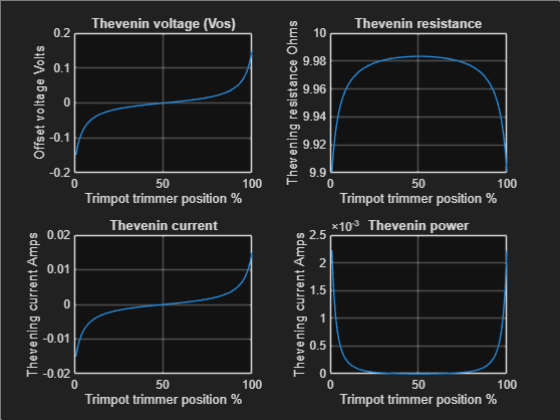

figure;
p = uipanel();
t = tiledlayout(p, 2,2);

nexttile(t)
plot(Vos);
title("Thevenin voltage (Vos)");
xlabel("Trimpot trimmer position %")
ylabel("Offset voltage Volts");
grid on;

nexttile(t)
plot(Rth);
title("Thevenin resistance");
xlabel("Trimpot trimmer position %")
ylabel("Thevening resistance Ohms");
grid on;

nexttile(t)
plot(Ith);
title("Thevenin current");
xlabel("Trimpot trimmer position %")
ylabel("Thevening current Amps");
grid on;

nexttile(t)
plot(Pth);
title("Thevenin power");
xlabel("Trimpot trimmer position %")
ylabel("Thevening current Amps");
grid on;

## Referenties

[Analog Devices. (2001, September 17). EPOT applications: Adjustment in op-amp circuits](https://www.analog.com/en/resources/technical-articles/epot-applications-adjustment-in-opamp-circuits.html)